## Creating The Low Pass Filter

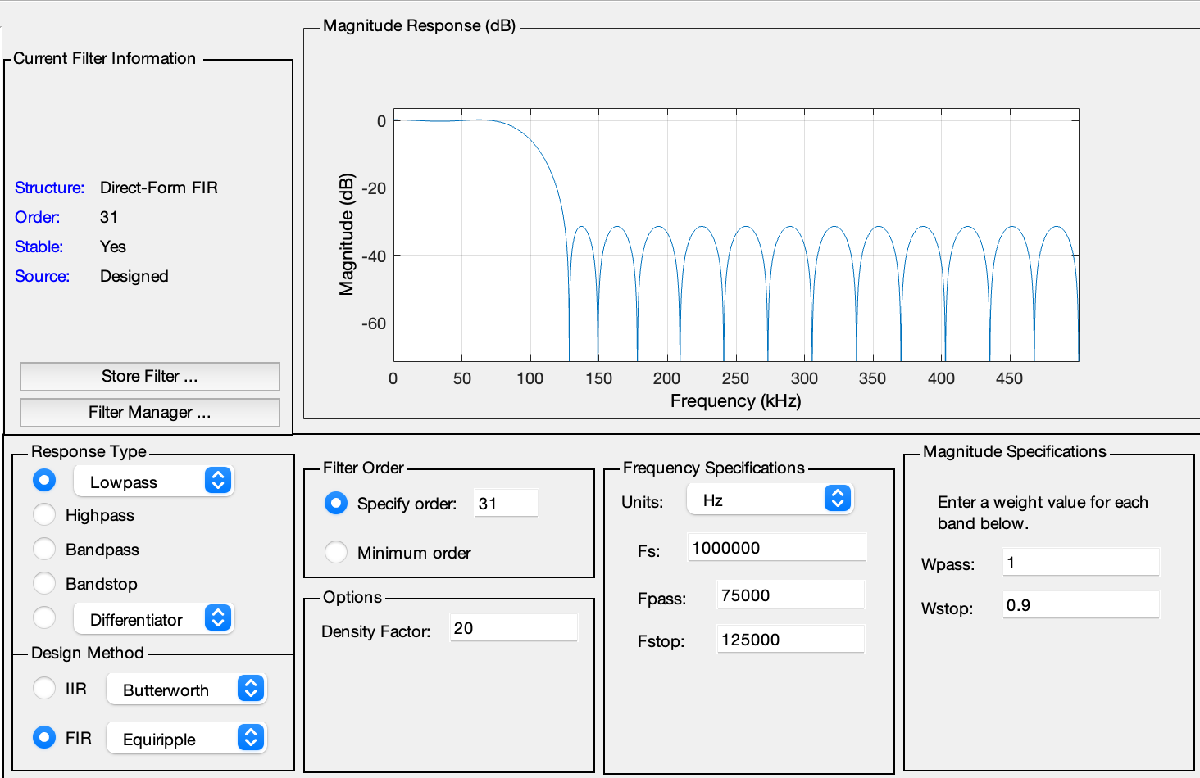

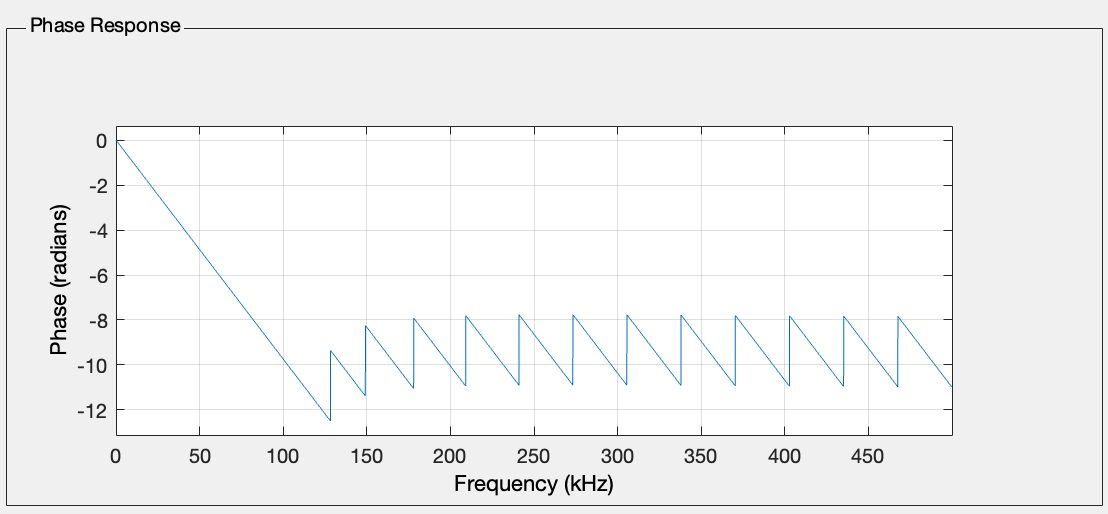

I have exported the coefficients of the above filter with the name of 'LPF' in the workspace.

## Filter after setting negative coefficients to zero

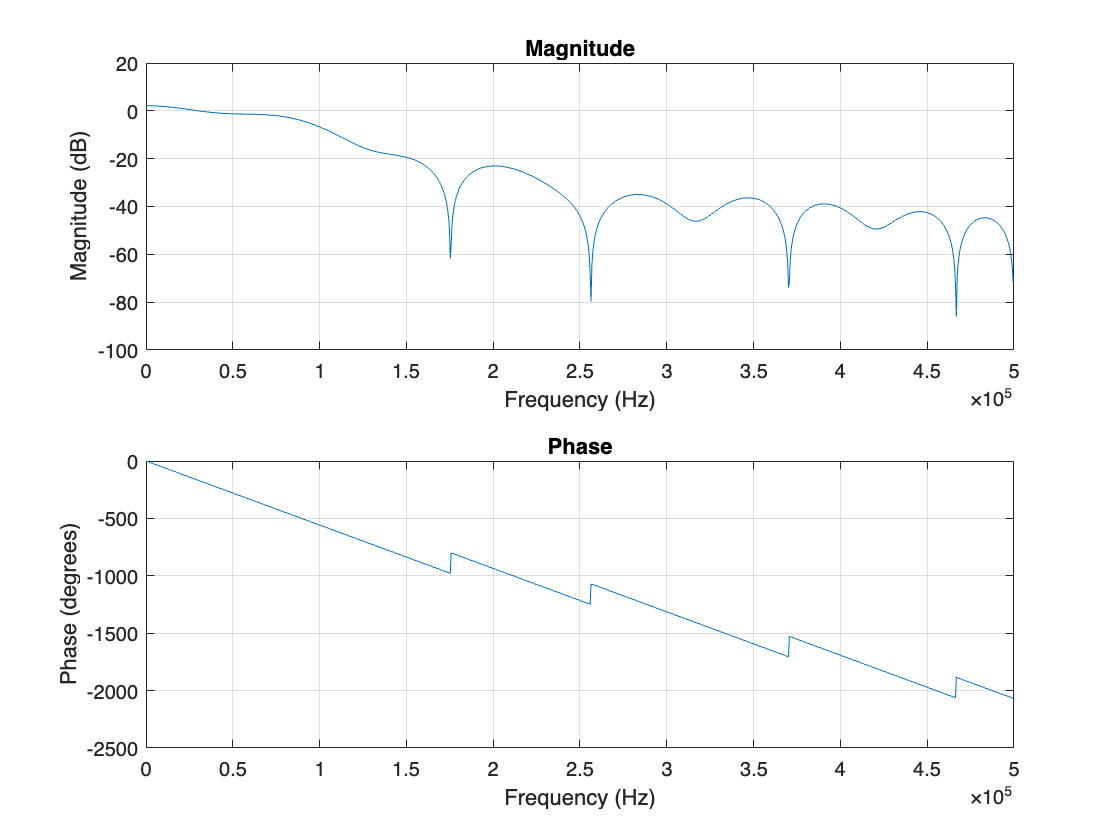

fs = 1e6; % Sampling frequency of 1 MHz
% Plot the magnitude response of the low-pass filter
freqz(LPF, 1, 1024, fs);
% title('Magnitude Response of Low-Pass Filter Without Negative Coefficients');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

## Testing the Filter on Matlab Generated Sine Waves

### 10kHz Matlab Generated Sine Wave Results

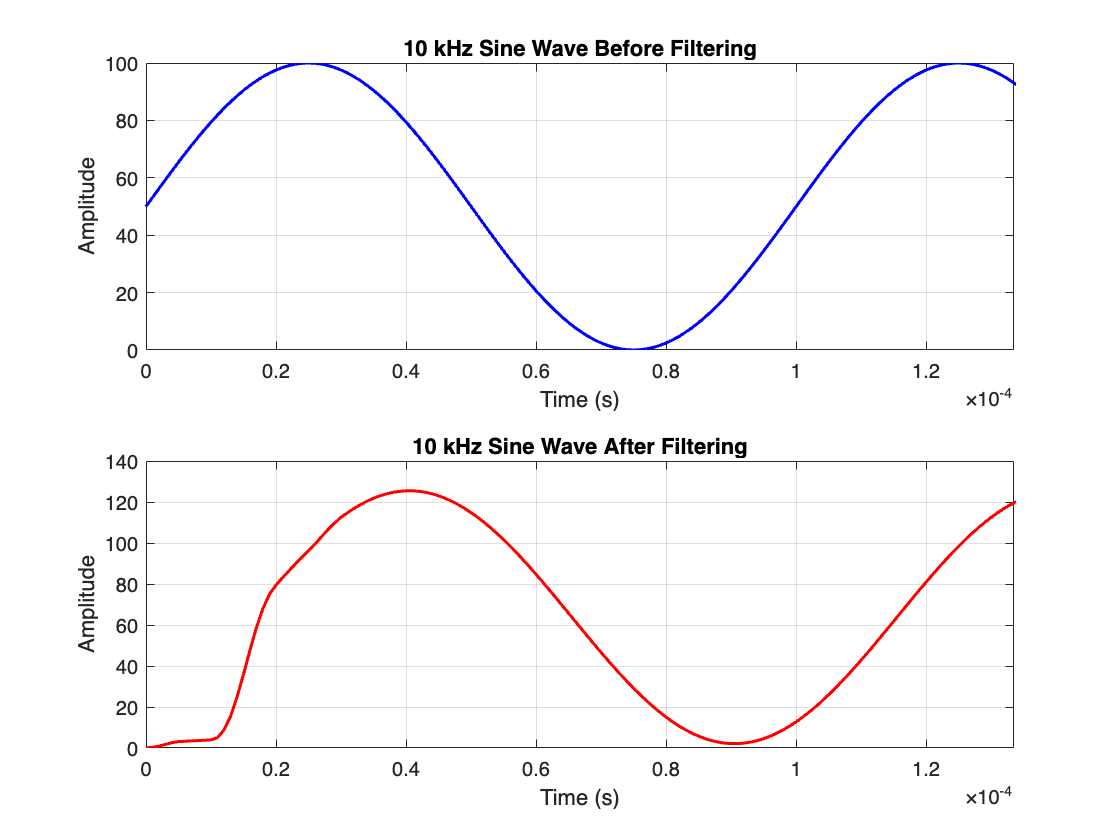

f_signal = 10e3; % Frequency of 10 kHz
t = 0:1/fs:1; % Time vector

x_signal = 50+50*sin(2*pi*f_signal*t); % Generate sine wave with offset
y_filtered = filter(LPF, 1, x_signal); % Filter 10 kHz sine wave

% Calculate the FFT of the original and filtered signals
fft_x_signal = fft(x_signal);
fft_y_filtered = fft(y_filtered);

% Frequency axis for plotting FFTs
f_axis = linspace(-fs/2, fs/2, length(fft_x_signal));

% Plot the 10 kHz sine wave before and after filtering
figure;
subplot(2, 1, 1);
plot(t, x_signal, 'b', 'LineWidth', 1.5);
xlim([0 0.0001335])
title('10 kHz Sine Wave Before Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(t, y_filtered, 'r', 'LineWidth', 1.5);
xlim([0 0.0001335])
title('10 kHz Sine Wave After Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

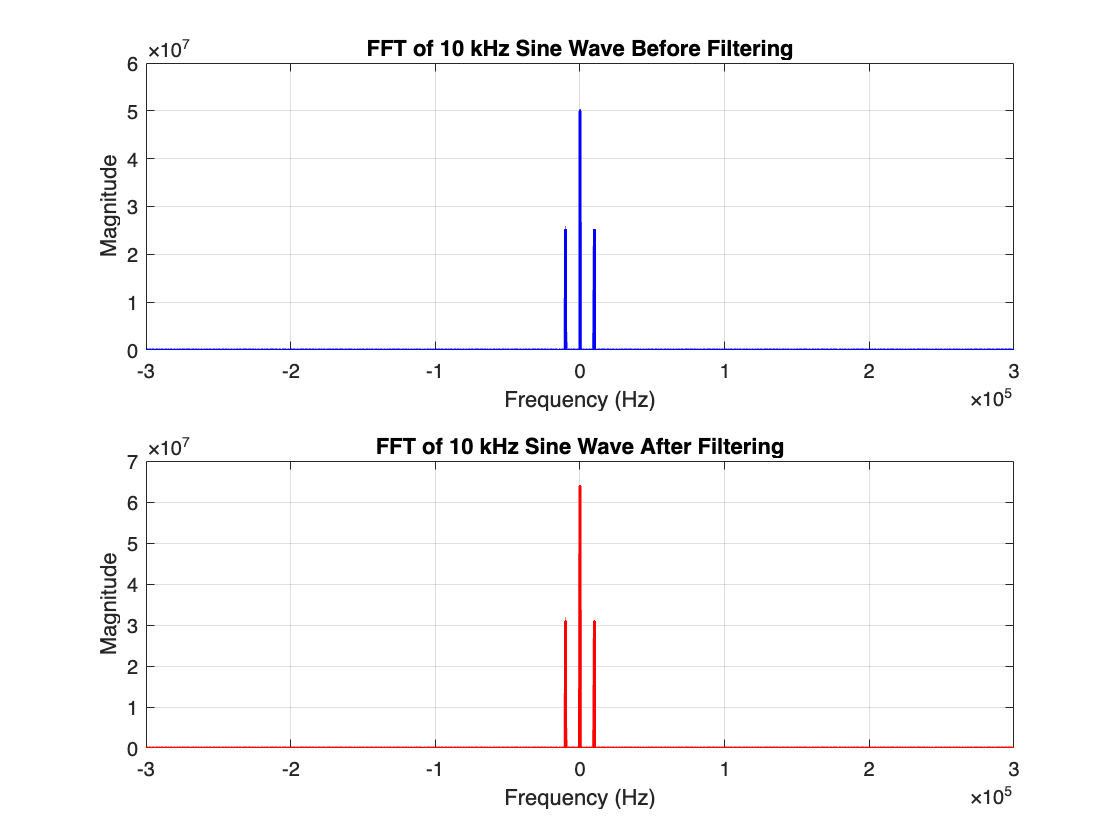

% Plot FFTs for 10 kHz sine wave
figure;
subplot(2, 1, 1);
plot(f_axis, fftshift(abs(fft_x_signal)), 'b', 'LineWidth', 1.5);
xlim([-300000 300000])
title('FFT of 10 kHz Sine Wave Before Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2, 1, 2);
plot(f_axis, fftshift(abs(fft_y_filtered)), 'r', 'LineWidth', 1.5);
xlim([-300000 300000])
title('FFT of 10 kHz Sine Wave After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

### 50kHz Matlab Generated Sine Wave Results

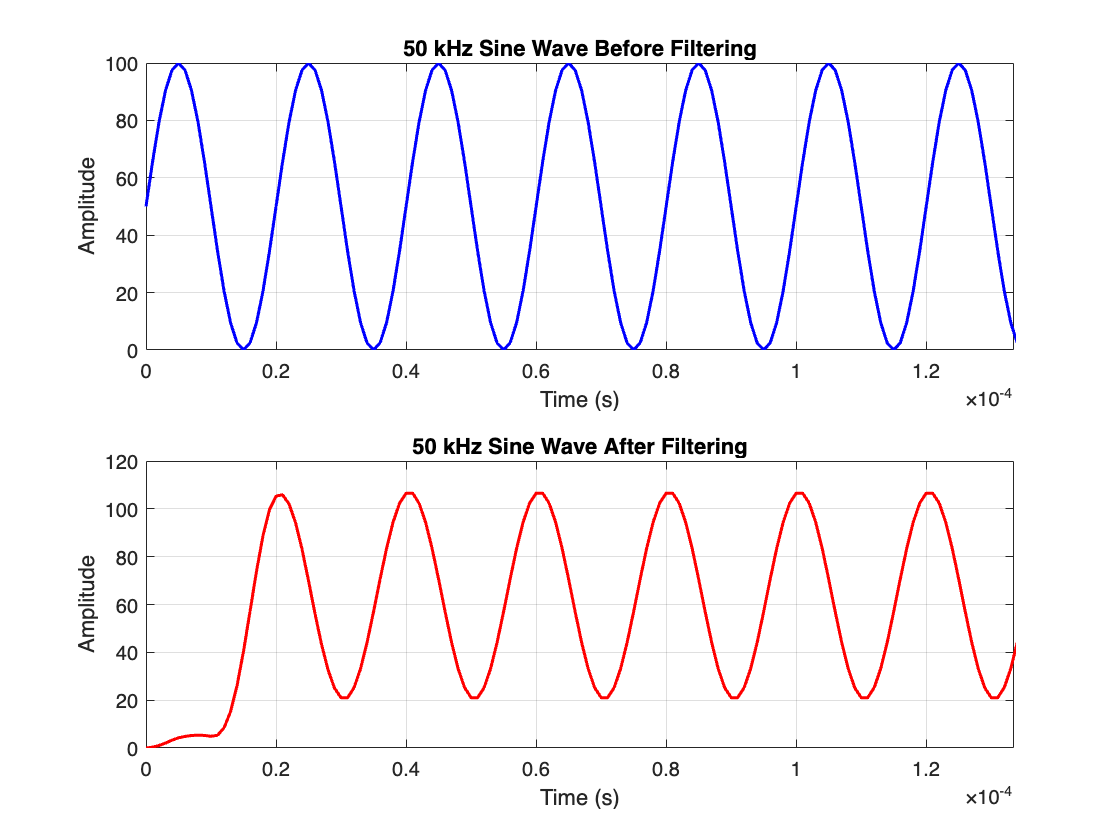

f_signal = 50e3; % Frequency of 50 kHz
t = 0:1/fs:1; % Time vector

x_signal = 50+50*sin(2*pi*f_signal*t); % Generate sine wave with offset
y_filtered = filter(LPF, 1, x_signal); % Filter 50 kHz sine wave

% Calculate the FFT of the original and filtered signals
fft_x_signal = fft(x_signal);
fft_y_filtered = fft(y_filtered);

% Frequency axis for plotting FFTs
f_axis = linspace(-fs/2, fs/2, length(fft_x_signal));

% Plot the 50 kHz sine wave before and after filtering
figure;
subplot(2, 1, 1);
plot(t, x_signal, 'b', 'LineWidth', 1.5);
xlim([0 0.0001335])
title('50 kHz Sine Wave Before Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(t, y_filtered, 'r', 'LineWidth', 1.5);
xlim([0 0.0001335])
title('50 kHz Sine Wave After Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

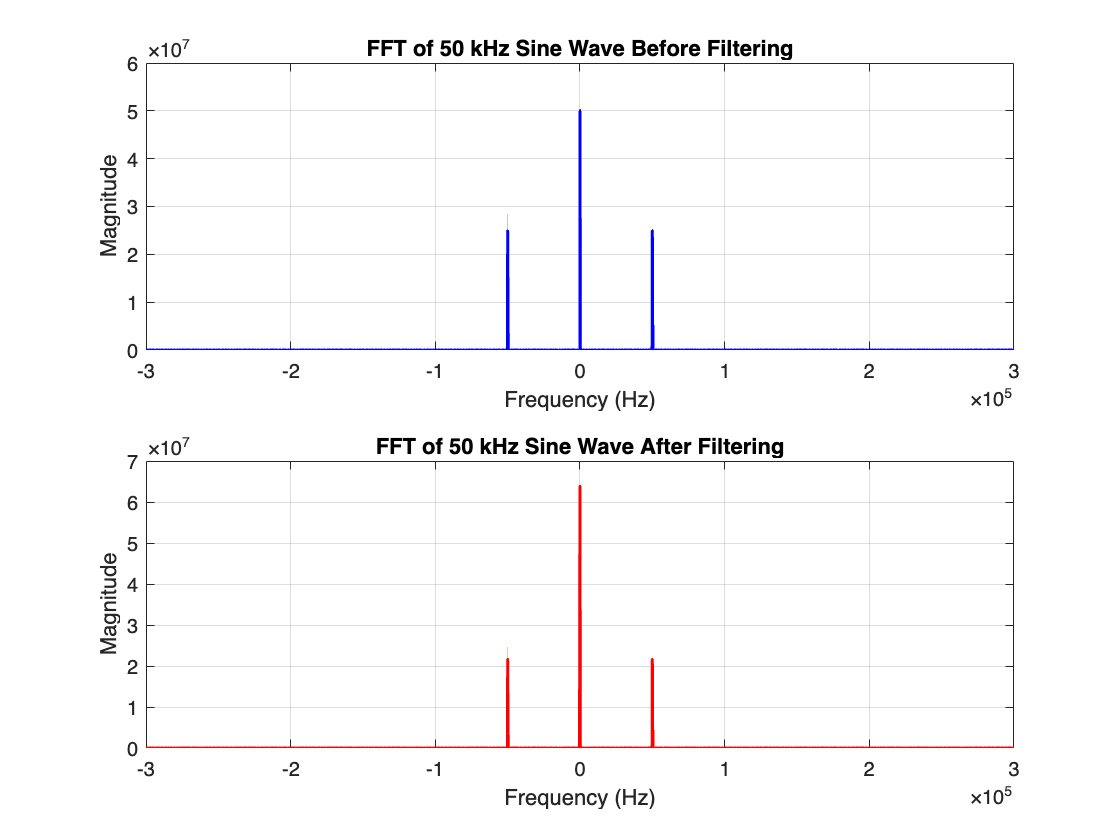

% Plot FFTs for 50 kHz sine wave
figure;
subplot(2, 1, 1);
plot(f_axis, fftshift(abs(fft_x_signal)), 'b', 'LineWidth', 1.5);
xlim([-300000 300000])
title('FFT of 50 kHz Sine Wave Before Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2, 1, 2);
plot(f_axis, fftshift(abs(fft_y_filtered)), 'r', 'LineWidth', 1.5);
xlim([-300000 300000])
title('FFT of 50 kHz Sine Wave After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

### 200kHz Matlab Generated Sine Wave Results

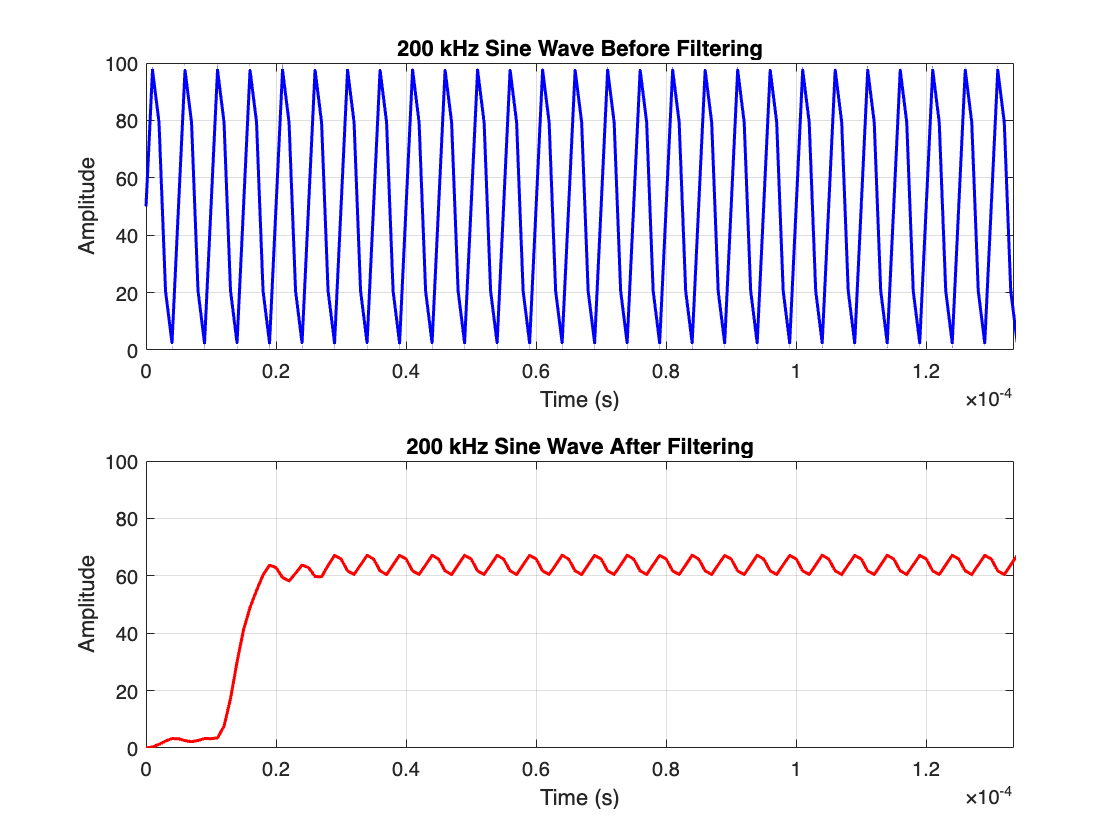

f_signal = 200e3; % Frequency of 200 kHz
t = 0:1/fs:1; % Time vector

x_signal = 50+50*sin(2*pi*f_signal*t); % Generate sine wave with offset
y_filtered = filter(LPF, 1, x_signal); % Filter 200 kHz sine wave

% Calculate the FFT of the original and filtered signals
fft_x_signal = fft(x_signal);
fft_y_filtered = fft(y_filtered);

% Frequency axis for plotting FFTs
f_axis = linspace(-fs/2, fs/2, length(fft_x_signal));

% Plot the 200 kHz sine wave before and after filtering
figure;
subplot(2, 1, 1);
plot(t, x_signal, 'b', 'LineWidth', 1.5);
xlim([0 0.0001335])
title('200 kHz Sine Wave Before Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(t, y_filtered, 'r', 'LineWidth', 1.5);
xlim([0 0.0001335])
ylim([0 100])
title('200 kHz Sine Wave After Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

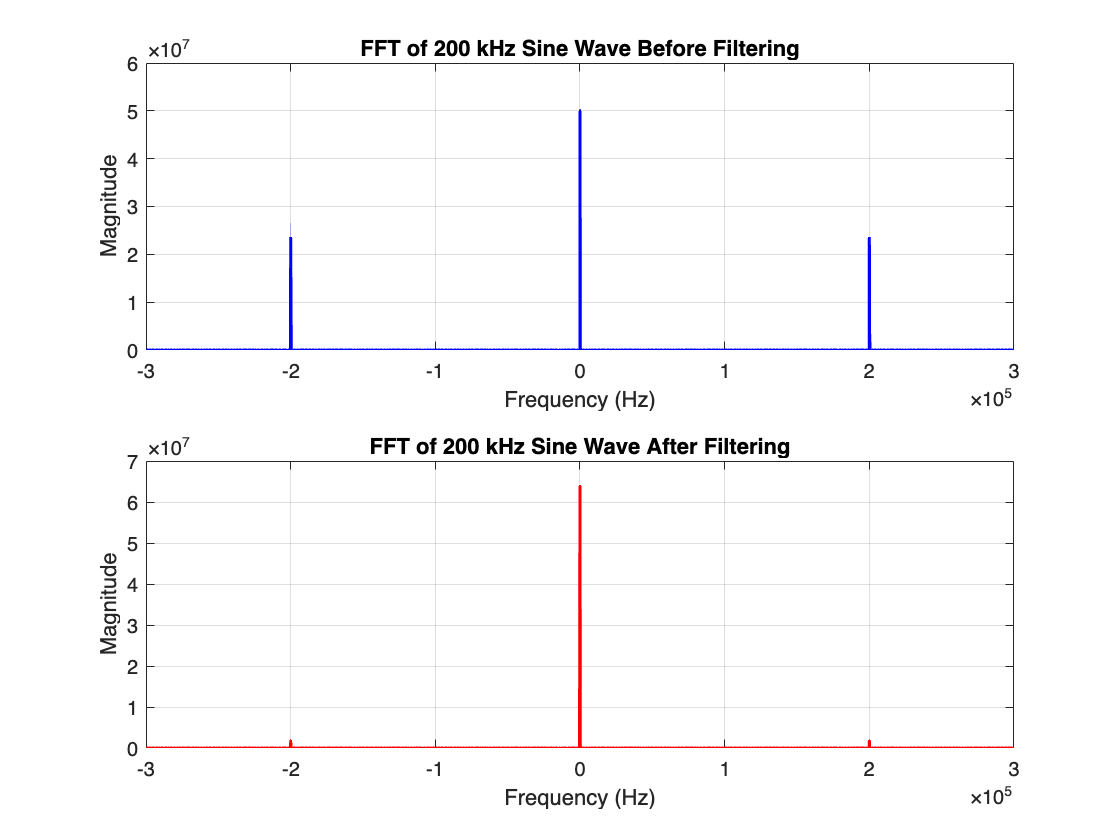

% Plot FFTs for 200 kHz sine wave
figure;
subplot(2, 1, 1);
plot(f_axis, fftshift(abs(fft_x_signal)), 'b', 'LineWidth', 1.5);
xlim([-300000 300000])
title('FFT of 200 kHz Sine Wave Before Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2, 1, 2);
plot(f_axis, fftshift(abs(fft_y_filtered)), 'r', 'LineWidth', 1.5);
xlim([-300000 300000])
title('FFT of 200 kHz Sine Wave After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

### 250kHz Matlab Generated Sine Wave Results

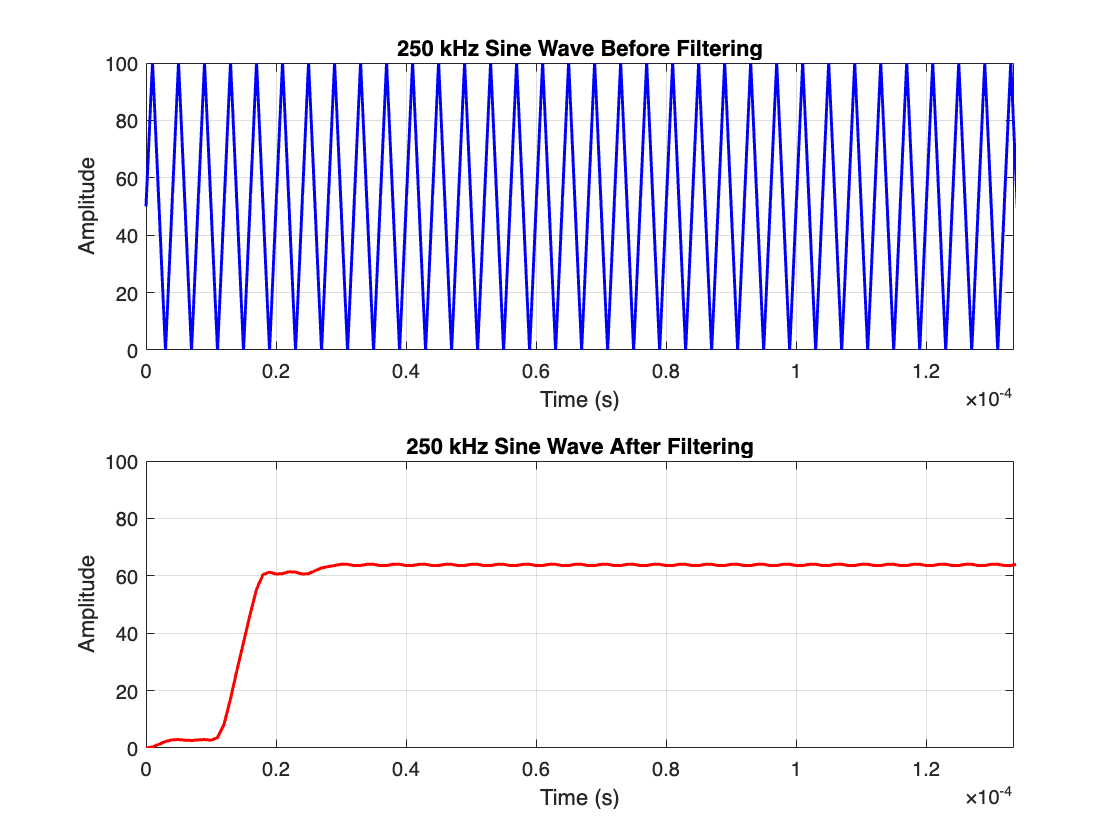

f_signal_high = 250e3; % Frequency of 250 kHz
x_signal_high = 50+50*sin(2*pi*f_signal_high*t); % Generate higher frequency sine wave with offset
y_filtered_high = filter(LPF, 1, x_signal_high); % Filter 250 kHz sine wave

% Calculate the FFT of the original and filtered signals
fft_x_signal_high = fft(x_signal_high);
fft_y_filtered_high = fft(y_filtered_high);

% Plot the 250 kHz sine wave before and after filtering
figure;
subplot(2, 1, 1);
plot(t, x_signal_high, 'b', 'LineWidth', 1.5);
xlim([0 0.0001335])
title('250 kHz Sine Wave Before Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(t, y_filtered_high, 'r', 'LineWidth', 1.5);
xlim([0 0.0001335])
ylim([0 100])
title('250 kHz Sine Wave After Filtering');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

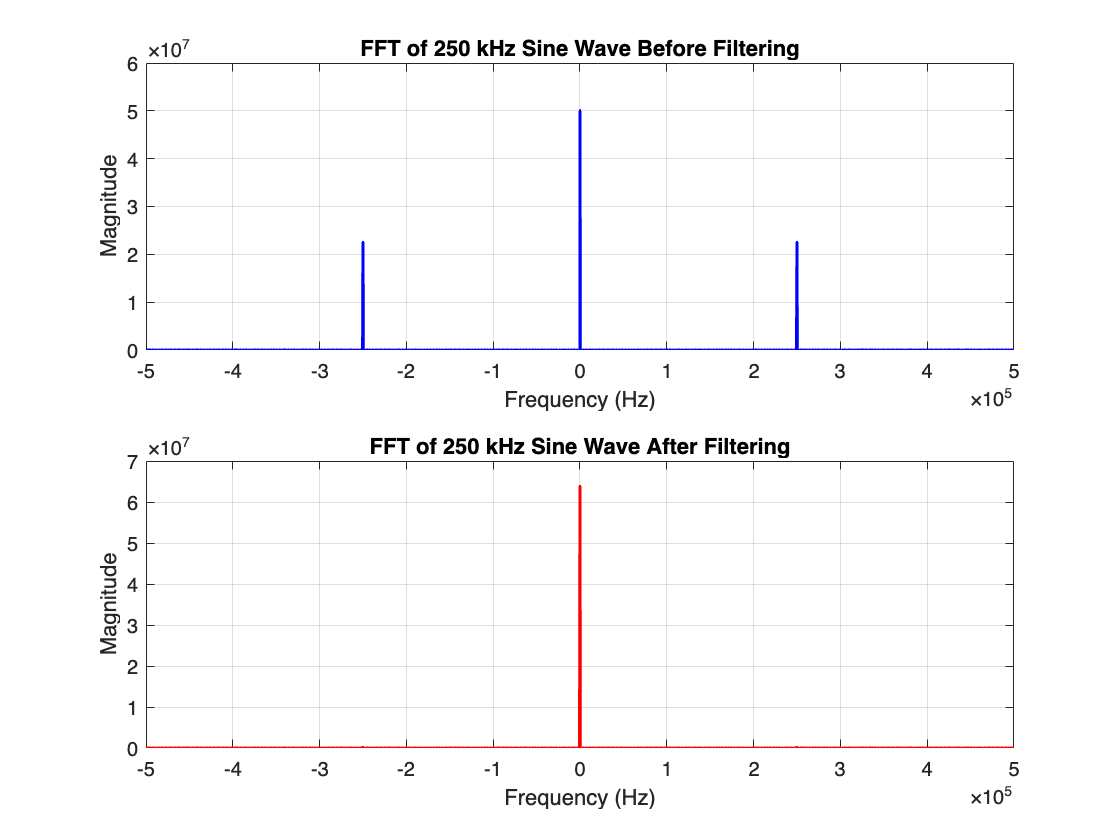

% Plot FFTs for 250 kHz sine wave
figure;
subplot(2, 1, 1);
plot(f_axis, fftshift(abs(fft_x_signal_high)), 'b', 'LineWidth', 1.5);
title('FFT of 250 kHz Sine Wave Before Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2, 1, 2);
plot(f_axis, fftshift(abs(fft_y_filtered_high)), 'r', 'LineWidth', 1.5);
title('FFT of 250 kHz Sine Wave After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

## Converting Filter Coefficients to 8 Bit Binary Representation

% Convert filter coefficients to 8-bit binary representation
bits = 8; % Number of bits for the binary representation
coeffs_binary = zeros(size(LPF), 'uint8'); % Initialize array to store binary representations

% Convert each coefficient to binary
for i = 1:numel(LPF)
    % Scale the coefficient to the range [0, 255] for 8-bit representation
    scaled_coeff = round(LPF(i) * 255);
    
    % Ensure the scaled coefficient is within the valid range
    scaled_coeff = max(0, min(255, scaled_coeff));
    
    % Convert the scaled coefficient to binary
    coeffs_binary(i) = uint8(scaled_coeff);
end

% Display the binary representation of coefficients
disp('Binary representation of filter coefficients:');

Binary representation of filter coefficients:


disp(coeffs_binary);

    0    2    3    4    4    2    0    0    0    0    0    5   18   32   44   50   50   44   32   18    5    0    0    0    0    0    2    4    4    3    2    0



## Verifying Verilog Filtered Output Results

### Testing on 10kHz Sine Wave Generated by our DDS

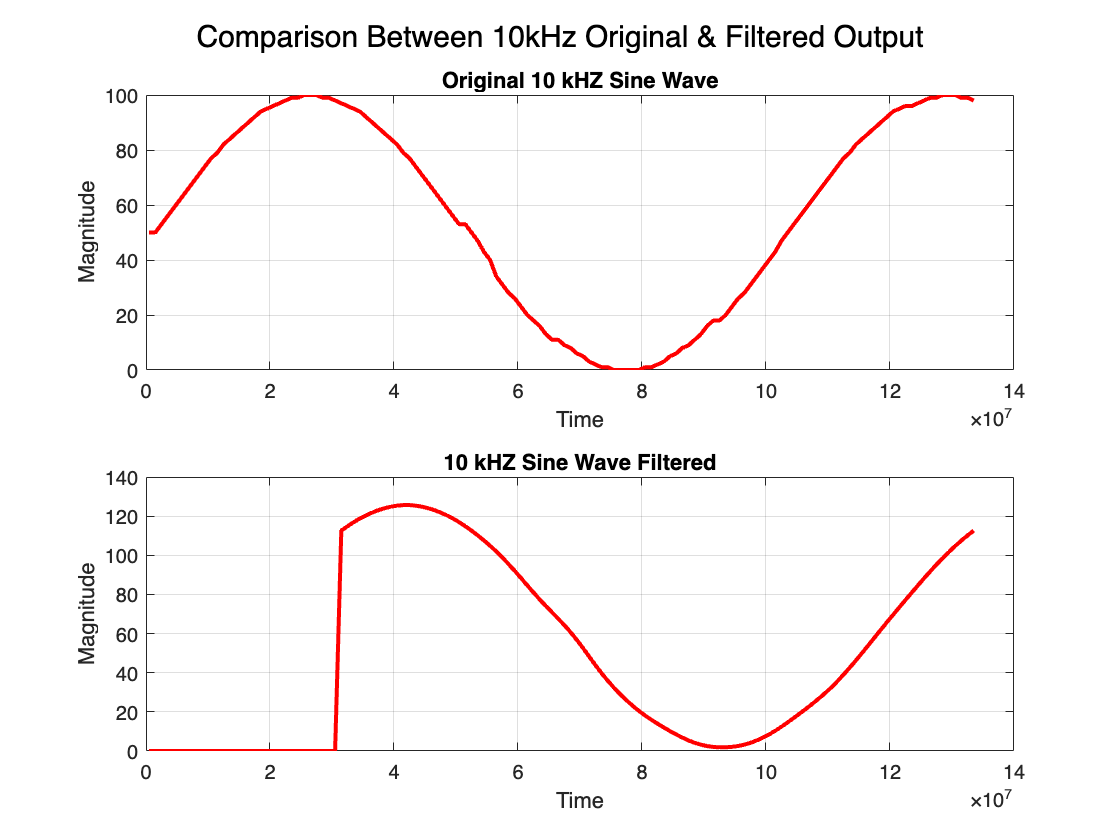

% Open the file for reading
fileID = fopen('10kHz_filtered.txt', 'r');
% Read the data using fscanf
data = fscanf(fileID, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d, Filtered_Output=%d\n', [4, Inf]);
% Close the file
fclose(fileID);
% Extract counter, DDS_Sin, and time values
time = data(1, :);
counter = data(2, :);
dds_sin = data(3, :);
fil_out = data(4, :);
% Plot the graphs
subplot(2,1,1)
plot(time, dds_sin, "r", "LineWidth", 2);
hold on
% stairs(time, dds_sin, "b", "LineWidth", 2);
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('Original 10 kHZ Sine Wave');
% Show the grid
grid on;
subplot(2,1,2)
plot(time, (fil_out/256), "r", "LineWidth", 2);
hold on
% stairs(time, (fil_out/256), "b", "LineWidth", 2);
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('10 kHZ Sine Wave Filtered');
% Show the grid
grid on;
sgtitle("Comparison Between 10kHz Original & Filtered Output")

### Testing on 50kHz Sine Wave Generated by our DDS

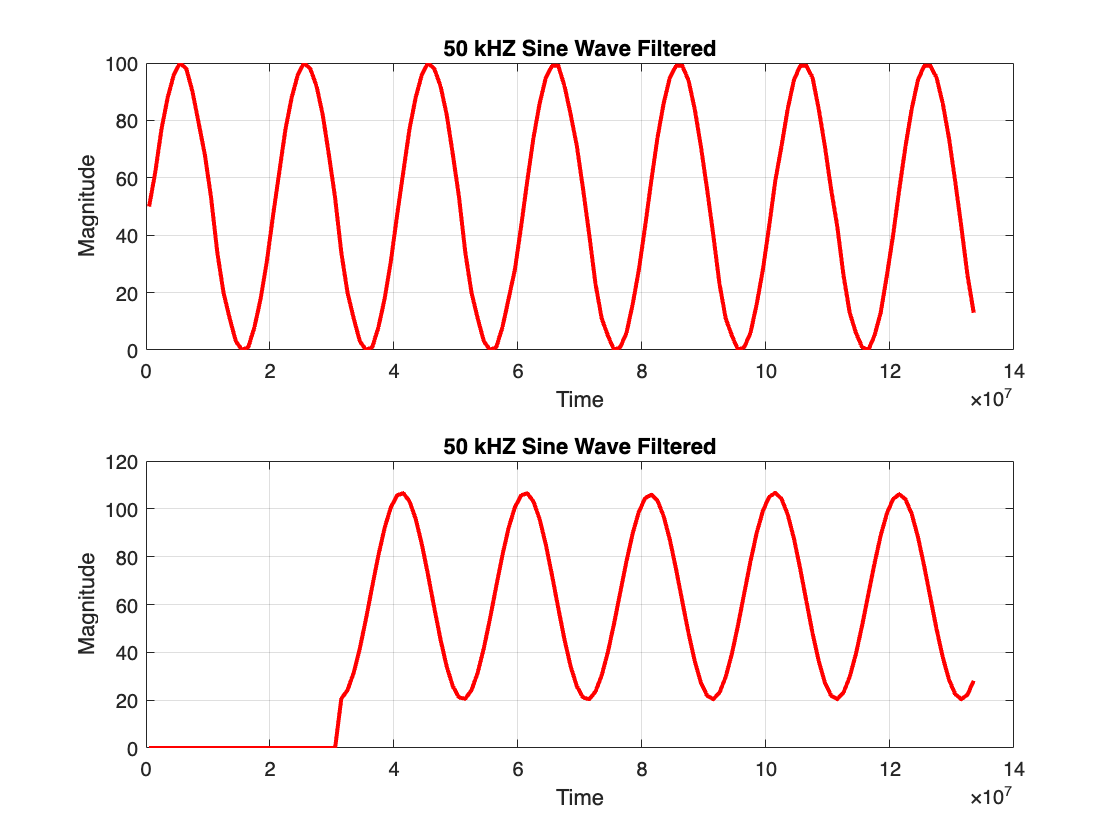

clf;
% Open the file for reading
fileID = fopen('50kHz_filtered.txt', 'r');
% Read the data using fscanf
data = fscanf(fileID, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d, Filtered_Output=%d\n', [4, Inf]);
% Close the file
fclose(fileID);
% Extract counter, DDS_Sin, and time values
time = data(1, :);
counter = data(2, :);
dds_sin = data(3, :);
fil_out = data(4, :);
% Plot the graphs
subplot(2,1,1)
plot(time, dds_sin, "r", "LineWidth", 2);
ylim([0 100])
hold on
% stairs(time, dds_sin, "b", "LineWidth", 2);
% ylim([0 100])
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('50 kHZ Sine Wave Filtered');
% Show the grid
grid on;
subplot(2,1,2)
plot(time, (fil_out/256), "r", "LineWidth", 2);
hold on
% stairs(time, (fil_out/256), "b", "LineWidth", 2);
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('50 kHZ Sine Wave Filtered');
% Show the grid
grid on;

### Testing on 200kHz Sine Wave Generated by our DDS

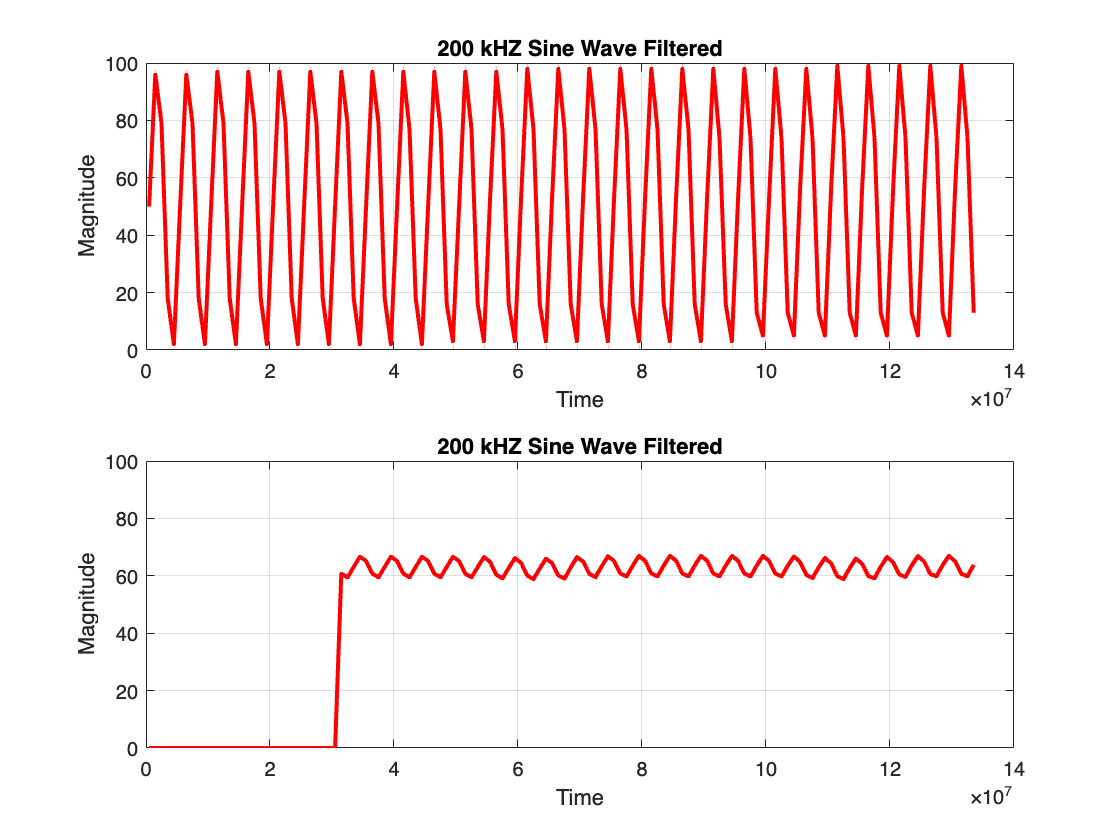

clf;
% Open the file for reading
fileID = fopen('200kHz_filtered.txt', 'r');
% Read the data using fscanf
data = fscanf(fileID, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d, Filtered_Output=%d\n', [4, Inf]);
% Close the file
fclose(fileID);
% Extract counter, DDS_Sin, and time values
time = data(1, :);
counter = data(2, :);
dds_sin = data(3, :);
fil_out = data(4, :);
% Plot the graphs
subplot(2,1,1)
plot(time, dds_sin, "r", "LineWidth", 2);
ylim([0 100])
hold on
% stairs(time, dds_sin, "b", "LineWidth", 2);
% ylim([0 100])
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('200 kHZ Sine Wave Filtered');
% Show the grid
grid on;
subplot(2,1,2)
plot(time, (fil_out/256), "r", "LineWidth", 2);
ylim([0 100])
hold on
% stairs(time, (fil_out/256), "b", "LineWidth", 2);
% ylim([0 100])
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('200 kHZ Sine Wave Filtered');
% Show the grid
grid on;

### Testing on 250kHz Sine Wave Generated by our DDS

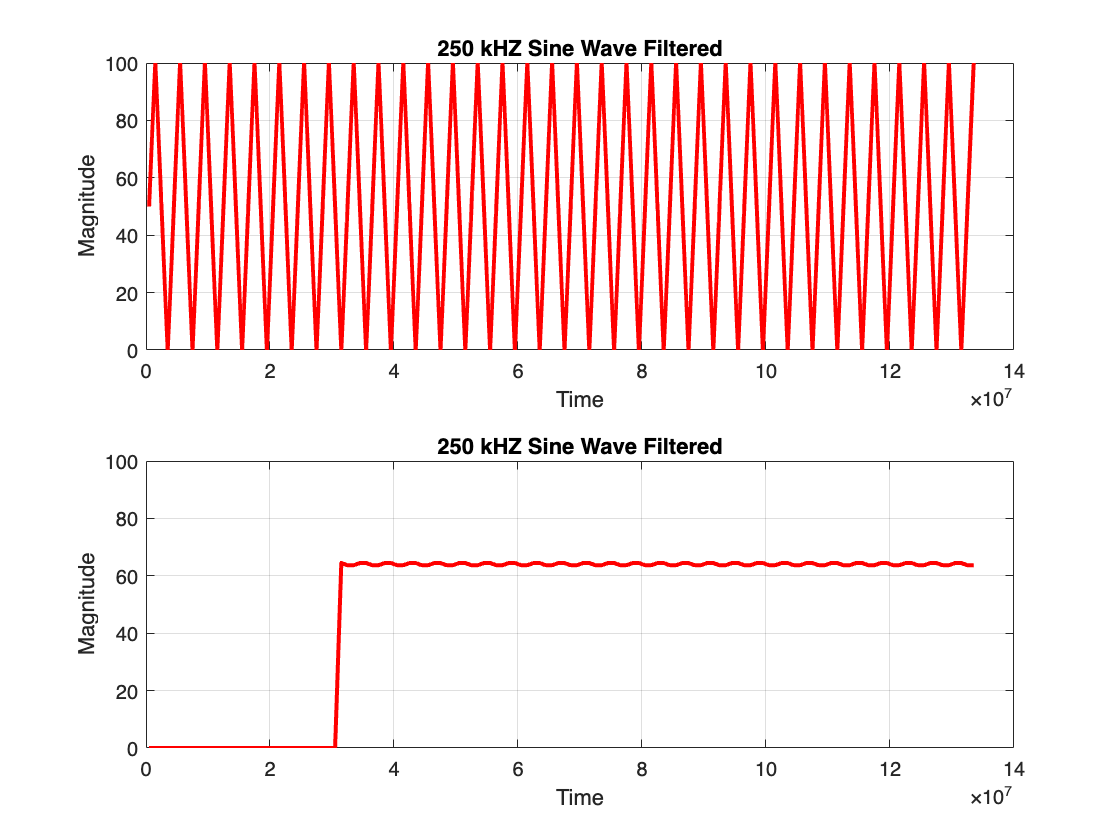

clf;
% Open the file for reading
fileID = fopen('250kHz_filtered.txt', 'r');
% Read the data using fscanf
data = fscanf(fileID, '# KERNEL: Time= %f, Counter= %d, DDS_Sin= %d, Filtered_Output=%d\n', [4, Inf]);
% Close the file
fclose(fileID);
% Extract counter, DDS_Sin, and time values
time = data(1, :);
counter = data(2, :);
dds_sin = data(3, :);
fil_out = data(4, :);
% Plot the graphs
subplot(2,1,1)
plot(time, dds_sin, "r", "LineWidth", 2);
ylim([0 100])
hold on
% stairs(time, dds_sin, "b", "LineWidth", 2);
% ylim([0 100])
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('250 kHZ Sine Wave Filtered');
% Show the grid
grid on;
subplot(2,1,2)
plot(time, (fil_out/256), "r", "LineWidth", 2);
ylim([0 100])
hold on
% stairs(time, (fil_out/256), "b", "LineWidth", 2);
% ylim([0 100])
hold off
% Add labels and title
% legend('Analog', 'Digital');
xlabel('Time');
ylabel('Magnitude');
title('250 kHZ Sine Wave Filtered');
% Show the grid
grid on;